# Plot Turbulence Empirical RSN filt (0.08-0.008)

Plot results from the empirical analysis: turbulence, information cascade flow, information cascade and information transfer obtained in turbulence_empirical_RSN.mlx. 

TBI dataset from OpenNeuro: [https://openneuro.org/datasets/ds000220/versions/1.0.0/file-display/dataset_description.json](https://openneuro.org/datasets/ds000220/versions/1.0.0/file-display/dataset_description.json)

## Load results

clear all
data_path='/Volumes/LASA/TBI_project/TBI_openneuro/timeseries/outputs/Turbulence_30_06_2022/';
output_path='/Volumes/LASA/TBI_project/TBI_openneuro/timeseries/outputs/Turbulence_30_06_2022/figures/';
addpath '/Users/noeliamartinezmolina/Documents/GitHub/TBI_turbulence_current_code/helper functions';
lambda={'0.27','0.24','0.21','0.18','0.15','0.12','0.09','0.06','0.03','0.01'};
LAMBDA=[0.27 0.24 0.21 0.18 0.15 0.12 0.09 0.06 0.03 0.01];
cond = {'tbi_s1','tbi_s2','tbi_s3','hc_s1'};
cd(data_path)
results_hc_s1 = load(sprintf('turbu_all_measurements__openneuro_controls_con1.mat'));
results_tbi_s1 = load(sprintf('turbu_all_measurements__openneuro_tbi_con1.mat'));
results_tbi_s2 = load(sprintf('turbu_all_measurements__openneuro_tbi_con2.mat'));
results_tbi_s3 = load(sprintf('turbu_all_measurements__openneuro_tbi_con3.mat'));

Turbu_hc_s1 = results_hc_s1.Turbulence_global_sub;
Turbu_tbi_s1 = results_tbi_s1.Turbulence_global_sub;
Turbu_tbi_s2 = results_tbi_s2.Turbulence_global_sub;
Turbu_tbi_s3 = results_tbi_s3.Turbulence_global_sub;

Turbu_RSN_hc_s1 = results_hc_s1.TurbulenceRSN_sub;
Turbu_RSN_tbi_s1 = results_tbi_s1.TurbulenceRSN_sub;
Turbu_RSN_tbi_s2 = results_tbi_s2.TurbulenceRSN_sub;
Turbu_RSN_tbi_s3 = results_tbi_s3.TurbulenceRSN_sub;

Info_flow_hc_s1 = results_hc_s1.TransferLambda_sub;
Info_flow_tbi_s1 = results_tbi_s1.TransferLambda_sub;
Info_flow_tbi_s2 = results_tbi_s2.TransferLambda_sub;
Info_flow_tbi_s3 = results_tbi_s3.TransferLambda_sub;

Info_cascade_hc_s1 = results_hc_s1.InformationCascade_sub;
Info_cascade_tbi_s1 = results_tbi_s1.InformationCascade_sub;
Info_cascade_tbi_s2 = results_tbi_s2.InformationCascade_sub;
Info_cascade_tbi_s3 = results_tbi_s3.InformationCascade_sub;

Info_transfer_hc_s1 = results_hc_s1.Transfer_sub;
Info_transfer_tbi_s1 = results_tbi_s1.Transfer_sub;
Info_transfer_tbi_s2 = results_tbi_s2.Transfer_sub;
Info_transfer_tbi_s3 = results_tbi_s3.Transfer_sub;

cd(output_path)

## Plot global Turbulence 3 Timepoints

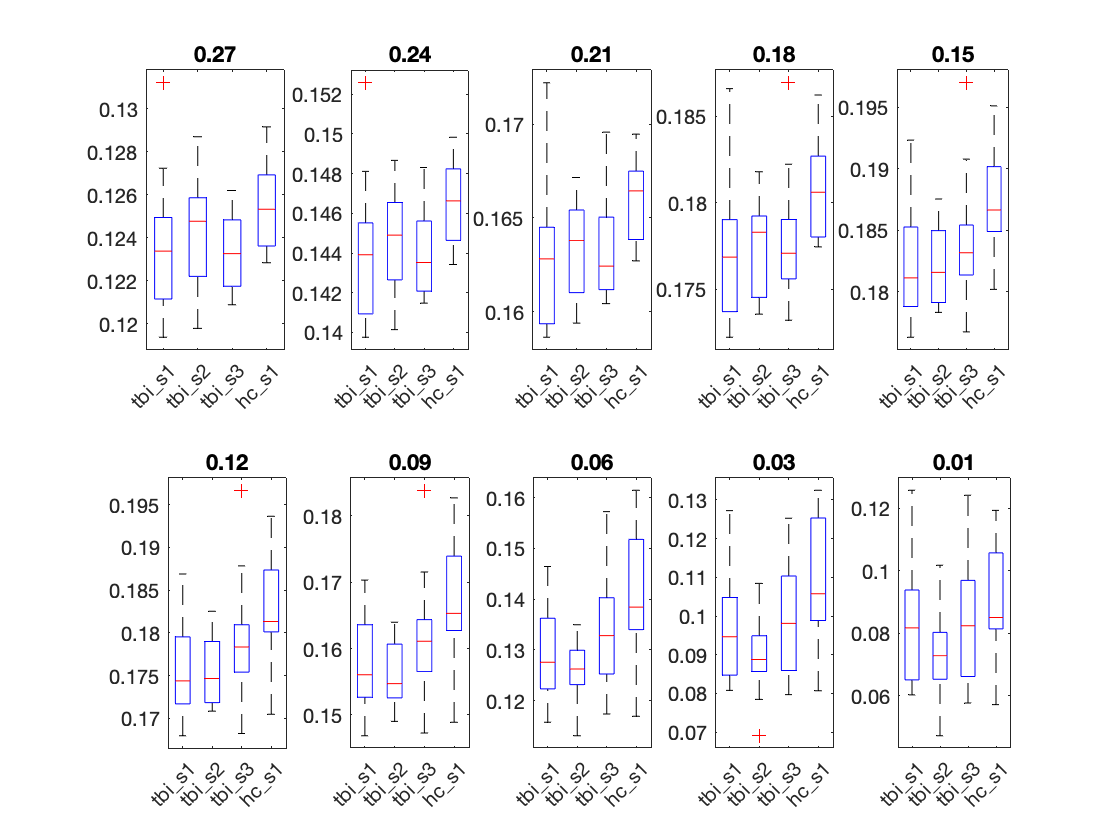

figure
for lamb=1:length(lambda)
    subplot(2,5,lamb)
    C = {Turbu_tbi_s1(lamb,:), Turbu_tbi_s2(lamb,:), Turbu_tbi_s3(lamb,:),Turbu_hc_s1(lamb,:)};    
    maxNumEl = max(cellfun(@numel,C));
    Cpad = cellfun(@(x){padarray(x(:),[maxNumEl-numel(x),0],NaN,'post')}, C);
    Cmat = cell2mat(Cpad);
    boxplot(Cmat,'Labels',cond)
    title(lambda{lamb})
end
print('Turbulence Global TBI Open Neuro TP123 (N=24) filt','-dpng')

close()

## Plot turbulence by RSN

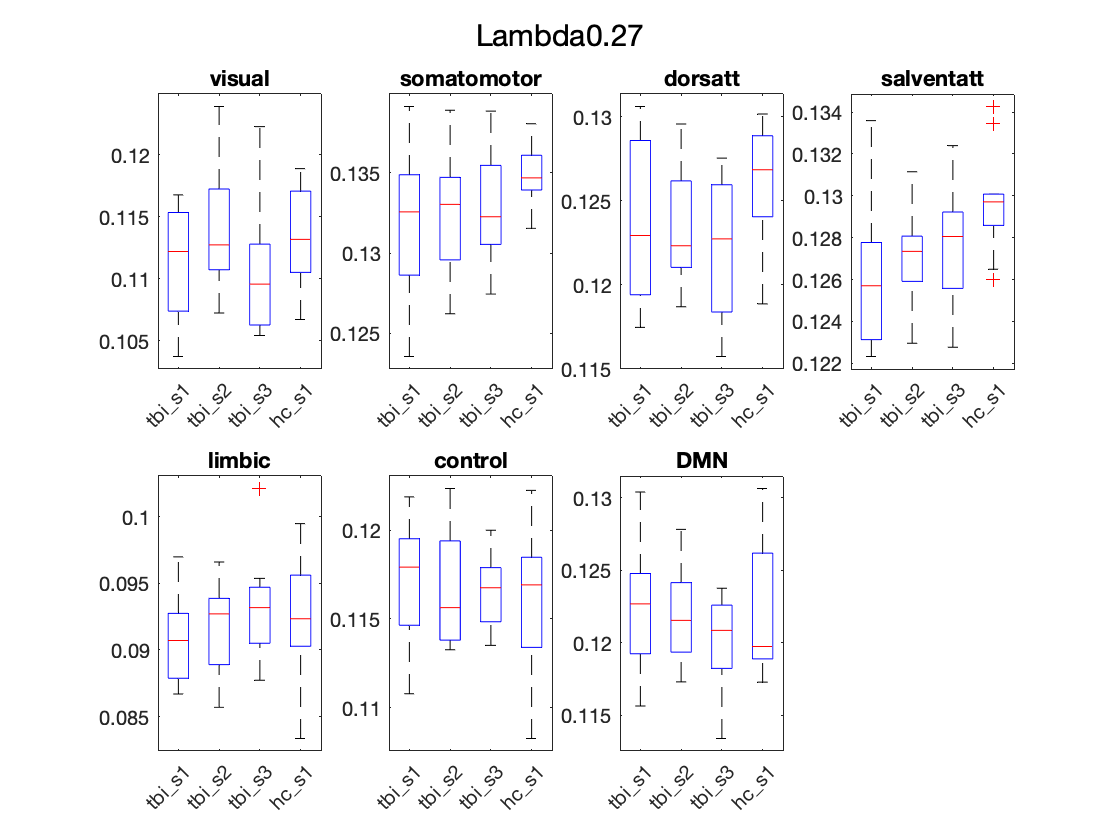

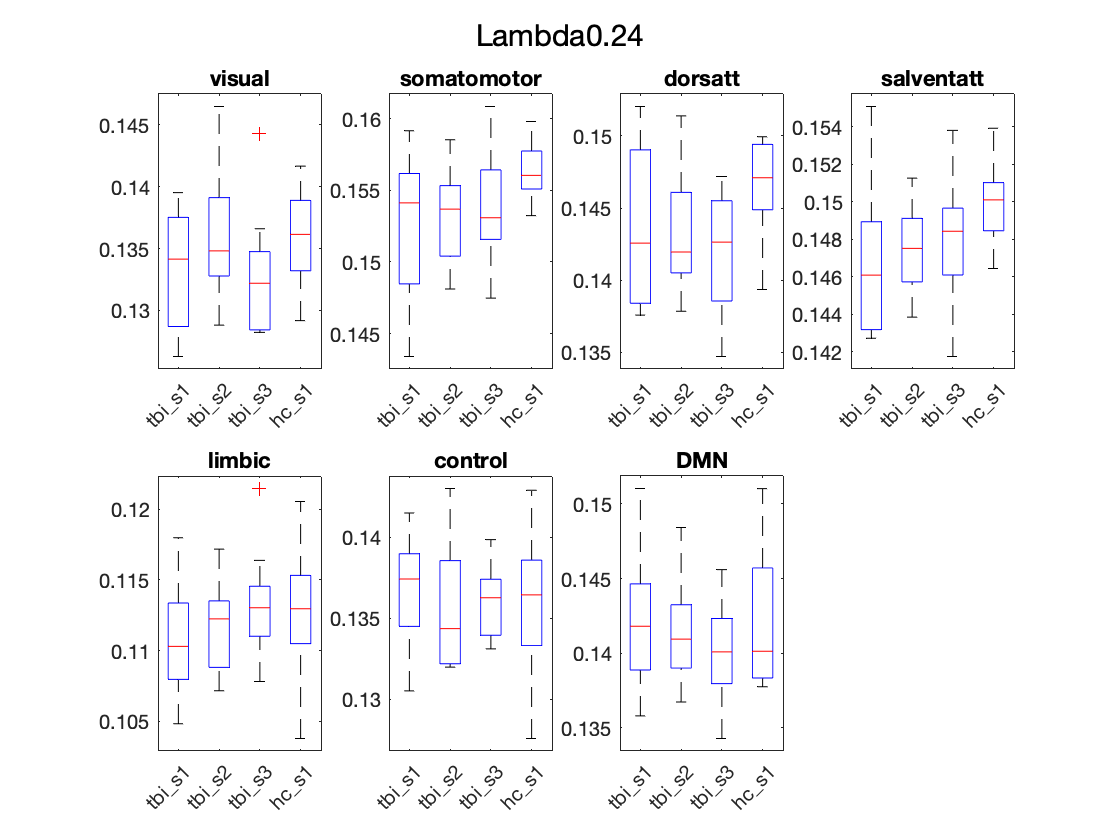

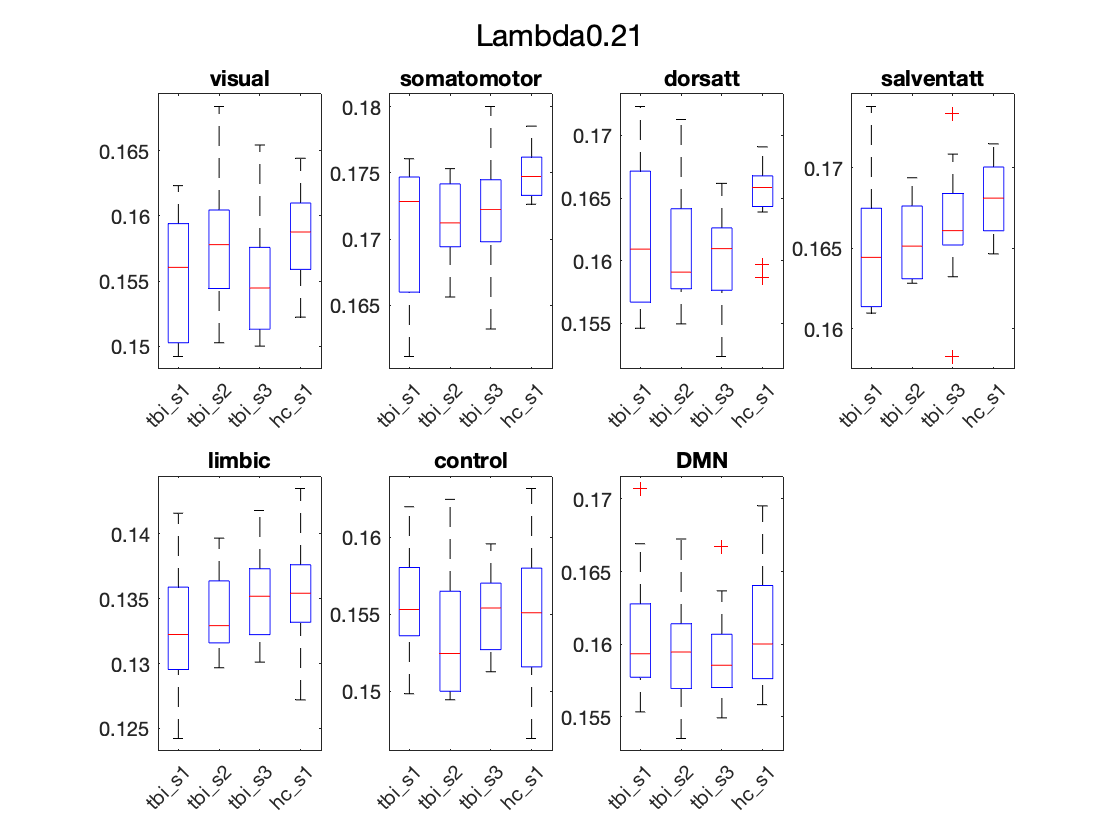

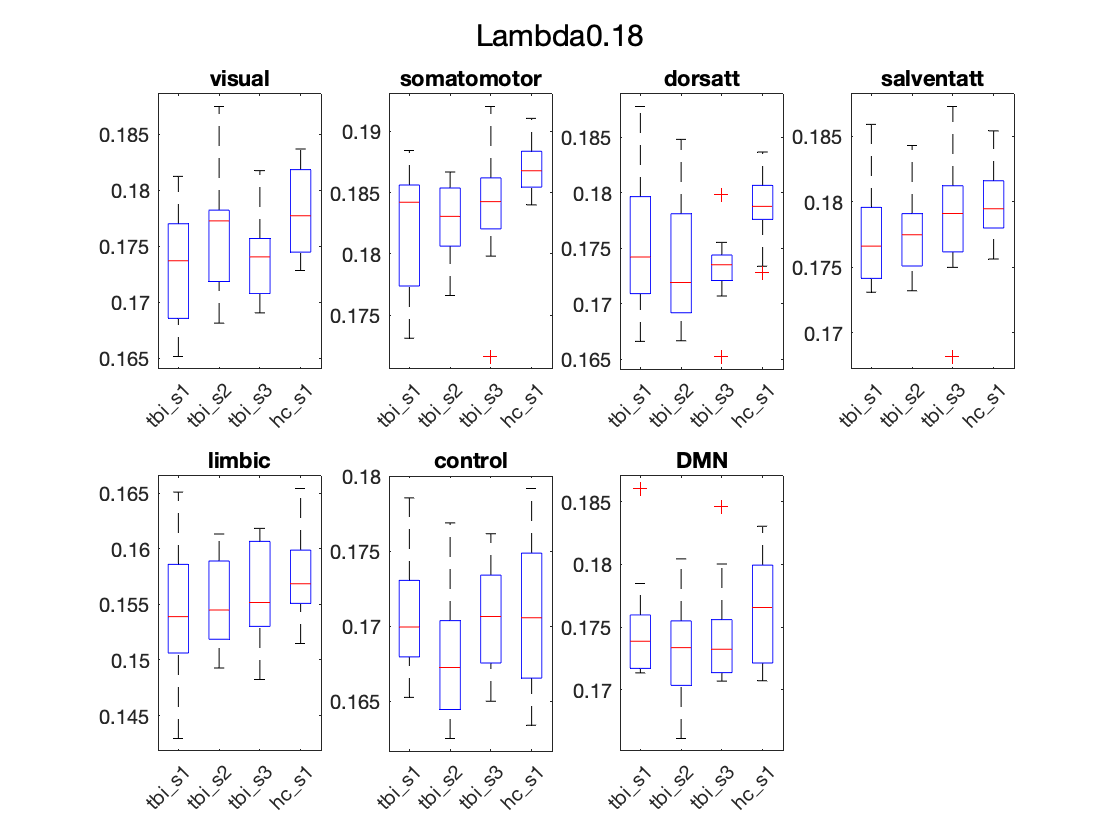

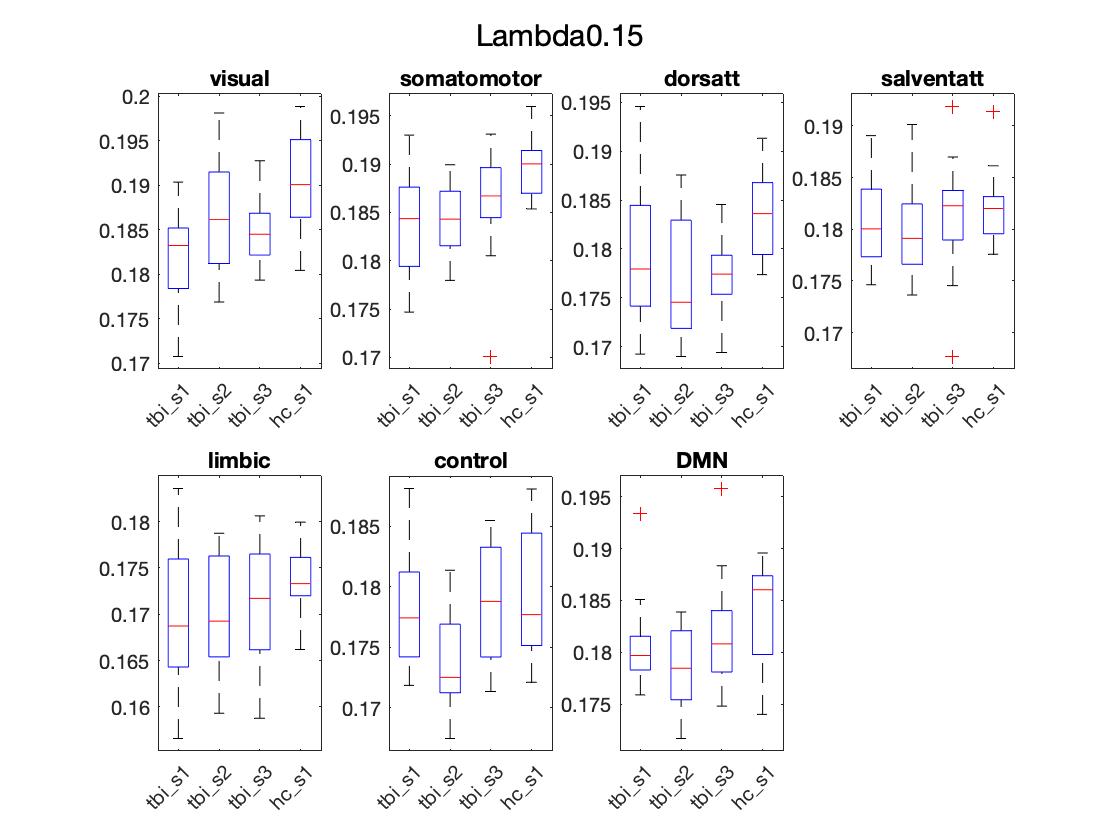

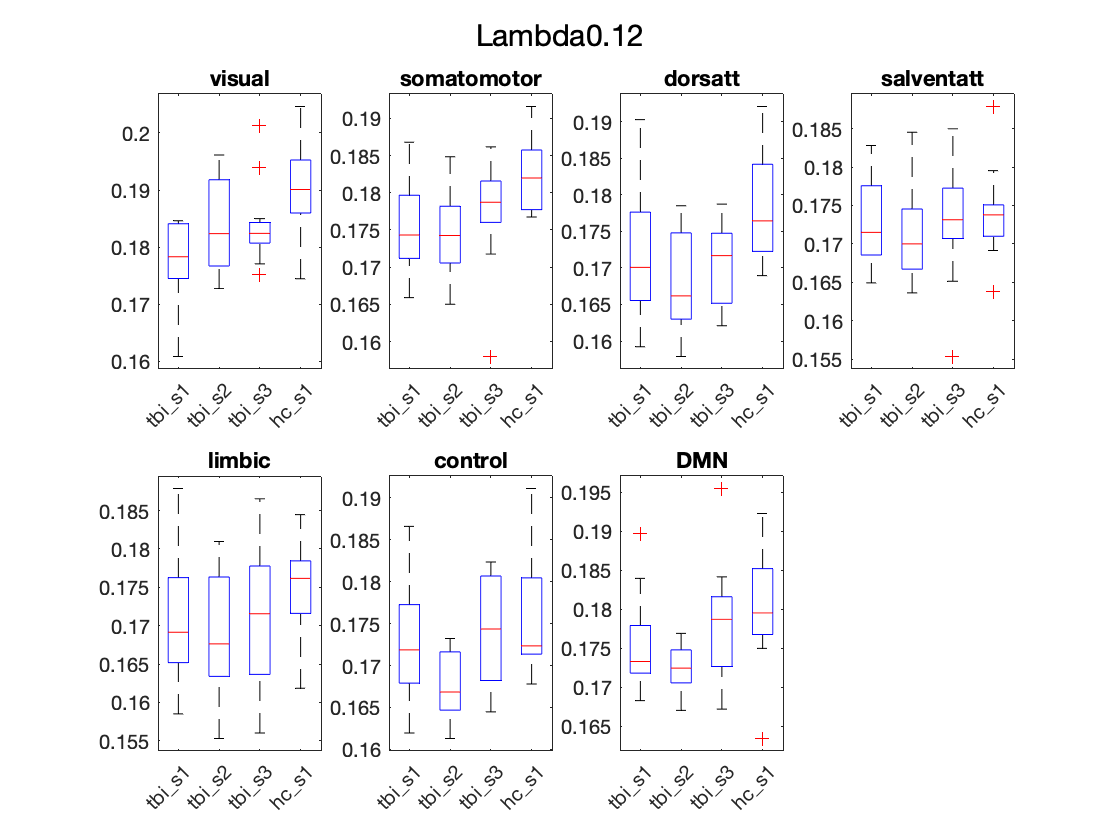

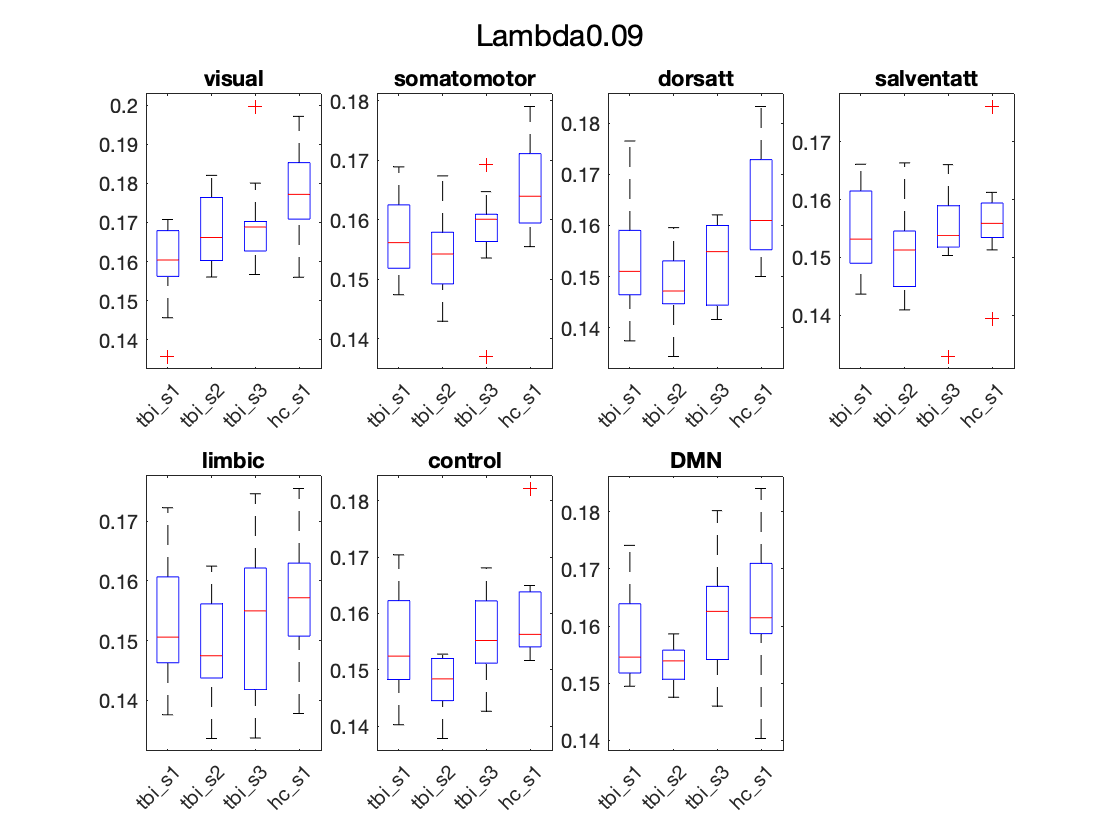

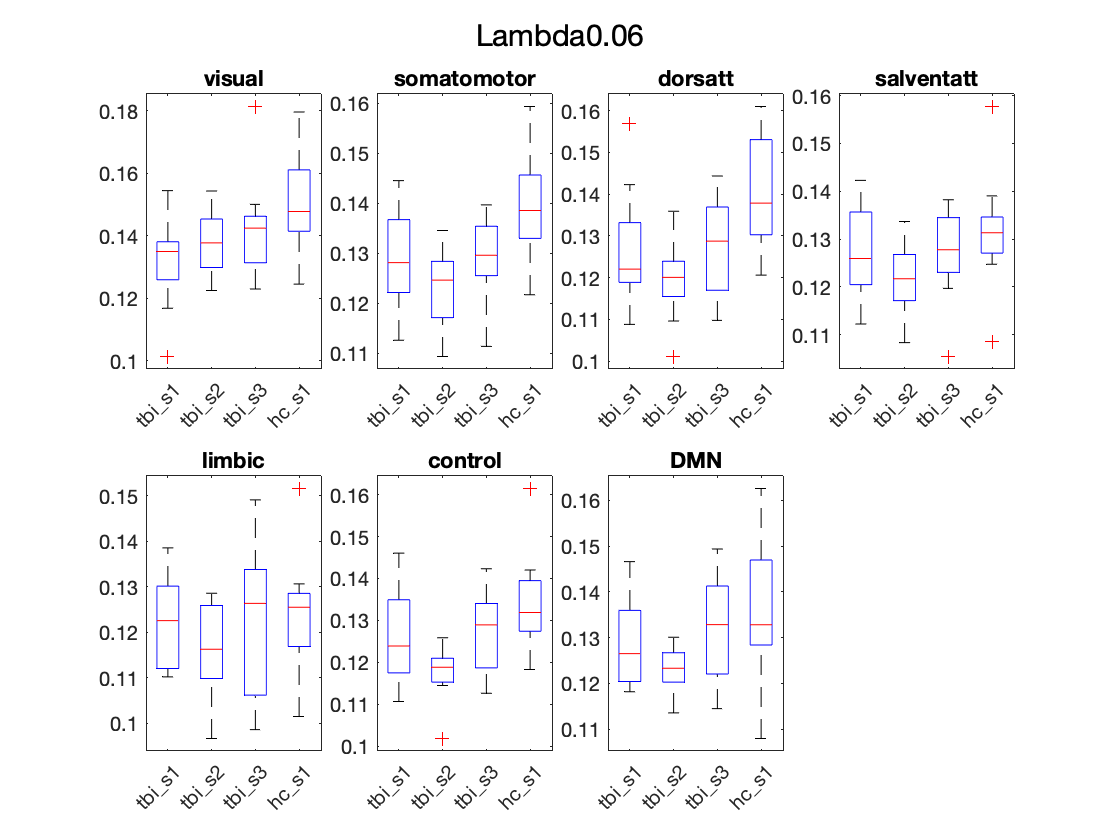

Rsns = {'visual', 'somatomotor','dorsatt','salventatt','limbic','control','DMN'};
for lamb=1:length(lambda)
    figure
    sgtitle (['Lambda' char(lambda(lamb))])
    for jj=1:7 %Loop for networks
        subplot(2,4,jj)
        C = {Turbu_RSN_tbi_s1(lamb,:,jj),Turbu_RSN_tbi_s2(lamb,:,jj),Turbu_RSN_tbi_s3(lamb,:,jj),Turbu_RSN_hc_s1(lamb,:,jj)};
        maxNumEl = max(cellfun(@numel,C));
        Cpad = cellfun(@(x){padarray(x(:),[maxNumEl-numel(x),0],NaN,'post')}, C);
        Cmat = cell2mat(Cpad);
        boxplot(Cmat,'Labels',cond)
        title(Rsns{jj})
    end
    print(['Turbulence RSN TBI Open Neuro TP123 (N=24) filt lambda' num2str(lamb)],'-dpng')
    saveas(gcf,['Turbulence RSN TBI Open Neuro TP123 (N=24) filt lambda' num2str(lamb)],'fig')
end

close()

## Plot information cascade flow

% All groups
figure;
shadedErrorBar(LAMBDA(2:length(LAMBDA)),Info_flow_tbi_s1(2:length(LAMBDA),:)',{@median,@std},'lineprops',{'r-o','markerfacecolor','r'});
hold on 
shadedErrorBar(LAMBDA(2:length(LAMBDA)),Info_flow_tbi_s2(2:length(LAMBDA),:)',{@median,@std},'lineprops',{'b-o','markerfacecolor','b'});
shadedErrorBar(LAMBDA(2:length(LAMBDA)),Info_flow_tbi_s3(2:length(LAMBDA),:)',{@median,@std},'lineprops',{'g-o','markerfacecolor','g'});
shadedErrorBar(LAMBDA(2:length(LAMBDA)),Info_flow_hc_s1(2:length(LAMBDA),:)',{@median,@std},'lineprops',{'c-o','markerfacecolor','c'});
ylabel('Information Flow');xlabel('Lambda Values')
legend(cond)
print('Info Flow TBI Open Neuro TP123 (N=24) filt','-dpng')
saveas(gcf,'Info Flow Open Neuro TP123 (N=24) filt','fig')
close()
% TBI patients only
figure;
shadedErrorBar(LAMBDA(2:length(LAMBDA)),Info_flow_tbi_s1(2:length(LAMBDA),:)',{@median,@std},'lineprops',{'b-o','markerfacecolor','b'});
hold on 
shadedErrorBar(LAMBDA(2:length(LAMBDA)),Info_flow_tbi_s2(2:length(LAMBDA),:)',{@median,@std},'lineprops',{'r-o','markerfacecolor','r'});
shadedErrorBar(LAMBDA(2:length(LAMBDA)),Info_flow_tbi_s3(2:length(LAMBDA),:)',{@median,@std},'lineprops',{'k-o','markerfacecolor','k'});
ylabel('Information Cascade Flow');xlabel('Lambda Values')
legend(cond)

print('Info Flow TBI Open Neuro TP123 Patients Only (N=24) filt','-dpng')
saveas(gcf,'Info Flow Open Neuro TP123 Patients Only filt','fig')
close()

## Plot information cascade

figure
C = {Info_cascade_tbi_s1,Info_cascade_tbi_s2,Info_cascade_tbi_s3,Info_cascade_hc_s1};
maxNumEl = max(cellfun(@numel,C));
Cpad = cellfun(@(x){padarray(x(:),[maxNumEl-numel(x),0],NaN,'post')}, C);
Cmat = cell2mat(Cpad);
boxplot(Cmat,'Labels',cond)
title('Information cascade')
print('Info Cascade TBI Open Neuro TP123 (N=24)filt lambda','-dpng')
saveas(gcf,'Info Cascade TBI Open Neuro TP123 (N=24) filt lambda','fig')
close()

## Plot information transfer

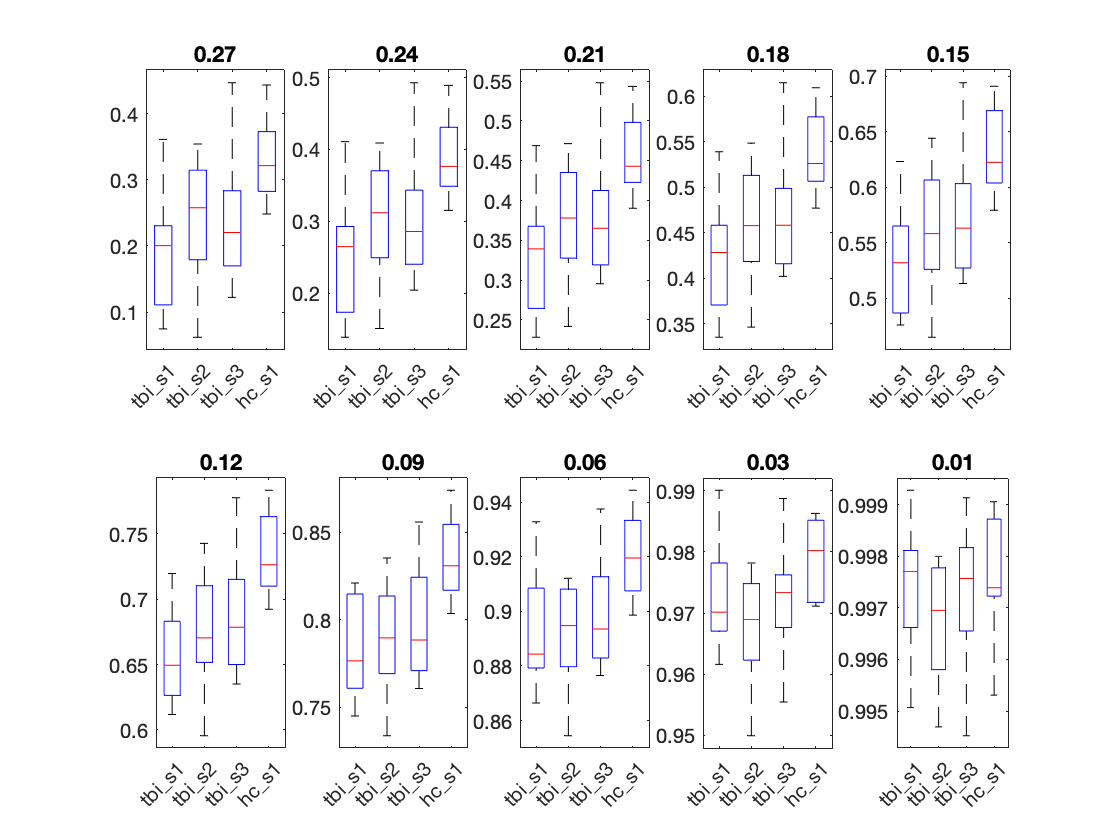

figure
for lamb=1:length(lambda)
    subplot(2,5,lamb)
    C = {1.-Info_transfer_tbi_s1(lamb,:),1.-Info_transfer_tbi_s2(lamb,:), 1.-Info_transfer_tbi_s3(lamb,:),1.-Info_transfer_hc_s1(lamb,:)};    
    maxNumEl = max(cellfun(@numel,C));
    Cpad = cellfun(@(x){padarray(x(:),[maxNumEl-numel(x),0],NaN,'post')}, C);
    Cmat = cell2mat(Cpad);
    boxplot(Cmat,'Labels',cond)
    title(lambda{lamb})
end
print('Info Transfer TBI Open Neuro TP123 (N=24)filt lambda','-dpng')

saveas(gcf,'Info Transfer TBI Open Neuro TP123 (N=24)filt lambda','fig')
close()